# Título de la actividad: Análisis de Deflexión en Vigas con Enfoque en Errores e Incertidumbres

## Integrantes

Nombres de los integrantes y el porcentaje de participación:

- Apellidos, nombres (100 %)

- Apellidos, nombres (Líder, 90 %)

- Apellidos, nombres (100 %)

- Apellidos, nombres (85 %)

## Objetivo de la actividad:

Evaluar el impacto de las incertidumbres en los parámetros de diseño sobre la deflexión máxima en vigas sometidas a cargas uniformemente distribuidas. Esta actividad permitirá a los estudiantes aplicar conceptos básicos de métodos numéricos y teoría de errores en el contexto de un problema de ingeniería civil.

## Contexto y escenario del problema:

Como parte del equipo de diseño para un nuevo proyecto de construcción, se requiere realizar un análisis preliminar de las vigas que formarán parte de la estructura de soporte de un edificio. Dado que las propiedades de los materiales y las cargas pueden tener variaciones, es crucial entender cómo estas incertidumbres afectan la seguridad y viabilidad del diseño. 

Para ello se te proporcionan los siguientes datos:

- Longitud de la viga $L$: $10 \pm 0.1\,\mathrm{m}$.

- Carga uniformemente distribuida $\omega$: $500  \pm 50\,\mathrm{N/m}$.

- Modulo de elasticidad $E$: $200 \pm 5\,\mathrm{GPa}$.

- Momento de inercia $I$: $5 \times 10^{-6}\,\mathrm{m^4}$ con una incertidumbre de $\pm 0.5 \times 10^{-6}\,\mathrm{m^4}$.

## Tarea detallada: 

Efectuar lo siguiente.

### Deflexión en vigas

- Investigue sobre la deflexión máxima en vigas y por qué es importante conocer dichos valores en construcción. *Use una herramienta de IA (ChatGPT, Copilot u otro) y compare con información certera obtenida de fuentes confiables. En el entregable debe colocar el prompt, la información obtenida por IA y la información que obtuvo de una fuente confiable*. 

Desarrolle aquí.

*** Inicio de ejemplo ***

**Fuentes chatGPT:**

Prompt: ¿Qué es el error relativo? Dame una definición matemática 

`Output: `

`El error relativo es una medida de la precisión de un valor aproximado en comparación con el valor real. Se define matemáticamente como: `$\text{Error relativo} = \frac{| \text{Valor aproximado} - \text{Valor real} |}{| \text{Valor real} |} \times 100\%$ 

`En esta fórmula, el valor aproximado es la estimación numérica que se obtiene mediante algún método de cálculo, y el valor real es el valor exacto o verdadero que se está tratando de aproximar. El error relativo proporciona una indicación de cuán cerca está el valor aproximado del valor real en términos relativos al tamaño del valor real. Es una medida útil para evaluar la precisión de los cálculos numéricos.`

Prompt: Escribe para mi una función en Matlab para calcular el error relativo de usar 3.14 como aproximación del número pi. 

`Output: `

`Claro, aquí tienes una función en MATLAB que calcula el error relativo al aproximar el número pi con 3.14:`

````matlab`

`function error_rel = calcular_error_pi()`

`    valor_real = pi;`

`    valor_aprox = 3.14;`

`    error_rel = abs(valor_aprox - valor_real) / abs(valor_real) * 100;`

`end`

`````

`Puedes llamar a esta función para obtener el error relativo:`

````matlab`

`error = calcular_error_pi();`

`disp(['El error relativo al aproximar pi con 3.14 es: ', num2str(error), '%']);`

`````

`Esta función calcula el error relativo y lo devuelve como un valor en porcentaje.`

Note que el resultado dado por ChatGPT no es preciso aunque si proporciona información en el contexto de los prompts. La forma de citar la información de las consultas a un chat de IA puede ser parafraseando las salidas y adjuntando un anexo con las preguntas y salidas tal cual. Otra forma de citar la información es parafrasear aquí y añadir un enlace a la sesión de consultas que realizó ([ejemplo de enlace](https://chat.openai.com/share/645171e7-4b46-4834-b1c2-1f5765948443)). 

**Fuentes confiables:**

Como se indica en Chapra (2012), el error relativo se calcula como $\xi = \frac{|A-a|}{|A|}$. A continuación se ilustra un ejemplo en Matlab. 

A=pi;
a=3.14;
da=error_rel(A,a)

da = 5.0696e-04

Esta definición es canónica, como se comprueba en la literatura (Dahlquist & Björck, 2003).

*** Fin de ejemplo ***

### Datos inciales

valL = 10; % m
valW = 500; % N/m
valE = 200e9; % Pa
valI = 5 * 10^-6; % m^4

errL = 0.1; % m
errW = 50; % N/m
errE = 5e9; % Pa
errI = 0.5 * 10^-6; % m^4

### Deflexión máxima     

- Cálculo de la deflexión máxima: Para ello debes usar la fórmula:  $y_{max} = \frac{5 \omega L^4}{384 E I}$

Desarrolle aquí.

% Programe aquí
syms W L E I
ymax_fn = @(W, L, E, I) (5 * W * L^4) / (384 * E * I);
ymax = ymax_fn(valW, valL, valE, valI)

ymax = 0.0651

### Cálculo de la incertidumbre

- Desarrolle un programa en MatLab que permita obtener la incertidumbre al calcular $y_{max}$. Al contratista se le da esta condición: *si el error relativo en el cálculo de la deflexión máxima es mayor que el 5%, entonces se deberá cambiar de material*. Responda si el contratista ejecutará dicho cambio.

Desarrolle aquí.

% Programe aquí
errYmax_syms = (abs(diff(ymax_fn(W, L, E, I), {W})) * errW) + (abs(diff(ymax_fn(W, L, E, I), {L})) * errL) + (abs(diff(ymax_fn(W, L, E, I), {E})) * errE) + (abs(diff(ymax_fn(W, L, E, I), {I})) * errI);
errYmax = double(subs(errYmax_syms, {W, L, E, I}, {valW, valL, valE, valI}))

errYmax = 0.0173

errPorYMax = (errYmax / ymax) * 100

errPorYMax = 26.5000

if errPorYMax > 5
    fprintf('El error relativo es mayor que 5%%. Se recomienda cambiar el material.\n');
else
    fprintf('El error relativo es menor que 5%%. No es necesario cambiar el material.\n');
end

El error relativo es mayor que 5%. Se recomienda cambiar el material.


### Análisis de sensibilidad 

- Analice el modelo matemático de la deflexion maxima $y_{max}$ considerando individualmente cada parámetro $(L, \omega, E, I)$ dentro de su rango de incertidumbre, manteniendo al resto constante, para evaluar cómo afecta en la variación de $y_{max}$. Existirá 4 casos e indique cual de las 4 variables genera una mayor incertidumbre en $y_{max}$.

Desarrolle aquí.

% Programe aquí
errYmax_W_syms = abs(diff(ymax_fn(W, L, E, I), {W})) * errW;
errYmax_W = double(subs(errYmax_W_syms, {W, L, E, I}, {valW, valL, valE, valI}))

errYmax_W = 0.0065


errYmax_L_syms = abs(diff(ymax_fn(W, L, E, I), {L})) * errL;
errYmax_L = double(subs(errYmax_L_syms, {W, L, E, I}, {valW, valL, valE, valI}))

errYmax_L = 0.0026


errYmax_E_syms = abs(diff(ymax_fn(W, L, E, I), {E})) * errE;
errYmax_E = double(subs(errYmax_E_syms, {W, L, E, I}, {valW, valL, valE, valI}))

errYmax_E = 0.0016

errYmax_I_syms = abs(diff(ymax_fn(W, L, E, I), {I})) * errI;
errYmax_I = double(subs(errYmax_I_syms, {W, L, E, I}, {valW, valL, valE, valI}))

errYmax_I = 0.0065

fprintf('Como podemos observar las variables W e I, son las que generan mayor incertidumbre, estando igualadas con 0.0065')

Como podemos observar las variables W e I, son las que generan mayor incertidumbre, estando igualadas con 0.0065

### Gráficos de sensibilidad

- Realice gráficos individuales (en MatLab para cada caso) entre la variación de cada magnitud versus el valor de la deflexión máxima e interprete cada gráfica.

Desarrolle aquí.

% Programe aquí
n = 100;
range_W = linspace(-errW, errW, n);
range_L = linspace(-errL, errL, n);
range_E = linspace(-errE, errE, n);
range_I = linspace(-errI, errI, n);

ymax_W = zeros(size(n));
ymax_L = zeros(size(n));
ymax_E = zeros(size(n));
ymax_I = zeros(size(n));

for i = 1:n
    ymax_W(i) = ymax_fn(valW + range_W(i), valL, valE, valI);
    ymax_L(i) = ymax_fn(valW, valL + range_L(i), valE, valI);
    ymax_E(i) = ymax_fn(valW, valL, valE + range_E(i), valI);
    ymax_I(i) = ymax_fn(valW, valL, valE, valI + range_I(i));
end

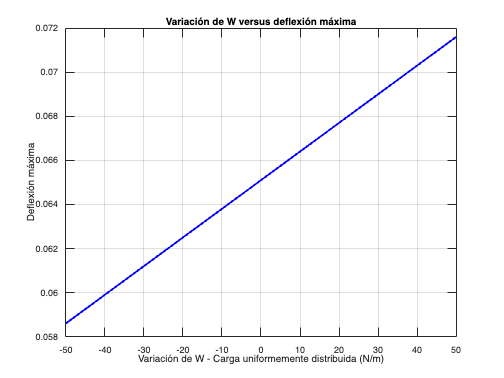

figure;
plot(range_W, ymax_W, 'b-', 'LineWidth', 2);
xlabel('Variación de W - Carga uniformemente distribuida (N/m)');
ylabel('Deflexión máxima');
title('Variación de W versus deflexión máxima');
grid on;

- Se observa que la deflexión máxima aumenta linealmente con la carga uniformemente distribuida (N/m) a medida que esta aumenta. Esto es típico en materiales done la deflexion es directamente proporcional a la carga aplicada hasta cierto punto antes de que el material falle o se deforme permanentemente.

- La tendencia general del gráfico sugiere que la relación entre la carga y la deflexión es lineal dentro del rango representado. Esto significa que la estructura se comporta de manera elástica, es decir, vuelve a su forma original después de retirar la carga. Sin embargo, esta relación puede cambiar si la carga supera cierto límite, lo que podría llevar a la deformación permanente o al fallo del material.

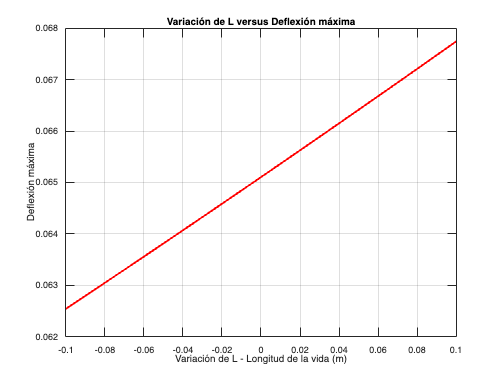

figure;
plot(range_L, ymax_L, 'r-', 'LineWidth', 2);
xlabel('Variación de L - Longitud de la vida (m)');
ylabel('Deflexión máxima');
title('Variación de L versus Deflexión máxima');
grid on;

- Se observa que la deflexión máxima aumenta linealmente con la longitud de la viga (L) a medida que esta aumenta.

- El gráfico sugiere que hay una correlación positiva entre la vida útil del material y su capacidad para soportar deflexiones. Este gráfico puede ser utilizado para predecir cómo las pequeñas variaciones en la longitud de la viga afectarán la deflexión máxima. Esto es crucial para garantizar que la viga mantendrá su integridad estructural y cumplirá con los requisitos de seguridad a lo largo de su vida útil, incluso con las incertidumbres inherentes a los materiales y las condiciones de carga.

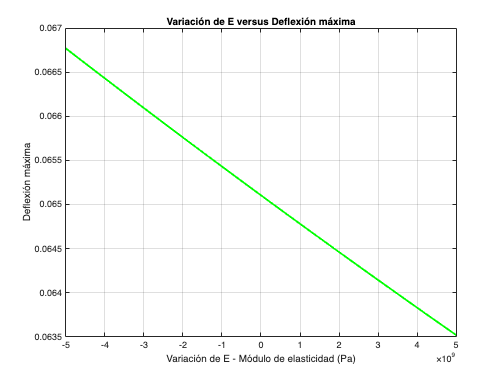

figure;
plot(range_E, ymax_E, 'g-', 'LineWidth', 2);
xlabel('Variación de E - Módulo de elasticidad (Pa)');
ylabel('Deflexión máxima');
title('Variación de E versus Deflexión máxima');
grid on;

- Se observa que la deflexión máxima disminuye linealmente con la variación del módulo de elasticidad (E) a medida que este aumenta. 

- Este comportamiento es crucial para garantizar la seguridad estructural del edificio, ya que una deflexión menor implica una viga más rígida y resistente.

- La presencia de incertidumbre en el momento de inercia debe ser considerada ya que podría afectar la rigidez y la capacidad de carga de la viga.

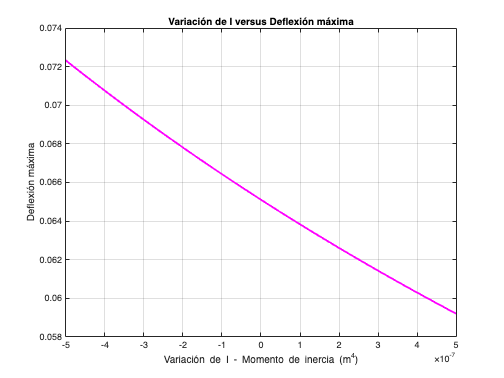

figure;
plot(range_I, ymax_I, 'm-', 'LineWidth', 2);
xlabel('Variación de I - Momento de inercia (m^4)');
ylabel('Deflexión máxima');
title('Variación de I versus Deflexión máxima');
grid on;

- Se observa que la deflexión máxima disminuye linealmente con la variación el momento de inercia (I) a medida que este aumenta. 

- Este análisis es esencial porque permite anticipar cómo las variaciones en las propiedades de los materiales afectarán el comportamiento de la viga bajo diferentes cargas.

- La variación del momento de inercia debe ser considerada cuidadosamente, ya que incertidumbres en esta propiedad pueden tener un impacto directo en la deflexión y, por ende, en la seguridad estructural.

### El factor rigidez

- ¿Cómo podría afectar una menor rigidez (menor módulo de elasticidad) a la seguridad y funcionalidad de una estructura? Evalúa los posibles riesgos asociados con la subestimación de la deflexión en el contexto de diferentes tipos de edificaciones, como hospitales, puentes o edificios residenciales.

Desarrolle aquí.

% Programe aquí
% Para analizar este caso, usaramos el ejemplo planteado y reduciremos su
% rigidez hasta 0 para observar como afecta  a la deflexión máxima de la estrcutura.

n = 100;
range_E = linspace(0, valE + errE, n);
ymax_E = zeros(size(n));

for i = 1:n
    ymax_E(i) = ymax_fn(valW, valL, range_E(i), valI);
end

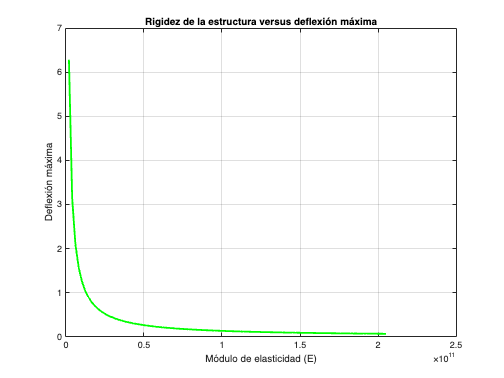

figure;
plot(range_E, ymax_E, 'g-', 'LineWidth', 2);
xlabel('Módulo de elasticidad (E)');
ylabel('Deflexión máxima');
title('Rigidez de la estructura versus deflexión máxima');
grid on;

Una menor rigidez, o un módulo de elasticidad reducido, puede tener impactos significativos en la seguridad y funcionalidad de estructuras. 

### Hospitales

**Riesgo de Daño a Equipos**: Equipos médicos sensibles pueden ser afectados por vibraciones o movimientos excesivos.

**Interrupción de Servicios**: La deflexión excesiva podría comprometer la operatividad durante emergencias o desastres.

**Seguridad del Paciente**: Vital para la seguridad de pacientes y personal.

### Puentes:

**Riesgo de Colapso**: Una deflexión no anticipada puede llevar al fallo estructural bajo cargas dinámicas o estáticas.

**Vibración Excesiva**: Puede causar incomodidad o inseguridad para los usuarios del puente.

### Edificios Residenciales:

**Daños Estructurales**: Grietas en paredes y problemas con marcos de puertas/ventanas.

**Seguridad de los Residentes**: En casos extremos, la seguridad de los ocupantes puede estar en riesgo.

#### Conclusion: La subestimación de la deflexión puede llevar a diseños que no cumplen con los estándares de seguridad y que podrían resultar en fallas estructurales o daños durante su vida útil.

## Referencias

- Chapra, S. C. (2012). *Applied numerical methods*. Columbus: McGraw-Hill.

- Dahlquist, G., & Björck, Å. (2003). *Numerical methods*. Courier Corporation.

## Funciones usadas

function da=error_rel(A,a)
    da=abs(A-a)/abs(A);
end